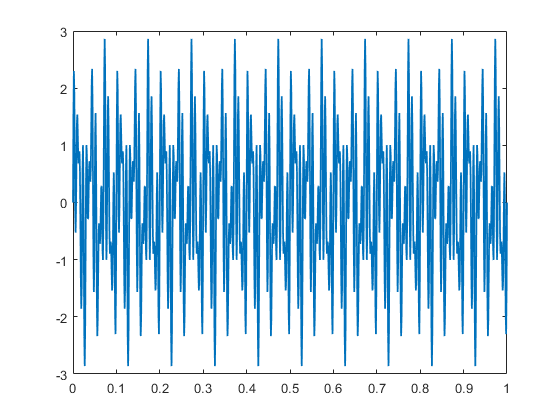

% Example for 1st signal
clear all

% create a signals with three frequencies
dt = 0.001;
ts=0:dt:1;
xs = sin(2*pi*30*ts) + sin(2*pi*100*ts) + sin(2*pi*140*ts); %w1=30Hz, w2=100Hz, w3=140Hz

figure(1);
plot(ts, xs, 'LineWidth', 1.3);


figure(2);
n=length(ts); % degree
fs = fft(xs, n); % fft
psd = fs.*conj(fs)/n; % power spectrum
ws = 1/(dt*n)*(0:n); %  x-axis of freqs in Hz
L = 1:floor(n/2);
plot(ws(L), psd(L));
ylabel('Power spectrum');
xlabel('Frequency (Hz)');


% Example for 2nd signal

%clear all; close all;

% create a signals with two frequencies

dt = 0.001;
ts=0:dt:1;
xs = sin(2*pi*30*ts) + sin(2*pi*100*ts) + sin(2*pi*140*ts); %w1=30Hz, w2=100Hz, w3=140Hz

figure(1);
plot(ts, xs, 'LineWidth', 1.3);


% we add noise here
sigma = 2;
ys = xs + sigma*randn(size(ts));

figure(2);
plot(ts(1:size(ts,2)/5), xs(1:size(ts,2)/5), 'k', 'LineWidth', 1.3);

hold on;
plot(ts(1:size(ts,2)/5), ys(1:size(ts,2)/5), 'r', 'LineWidth', 1.3);

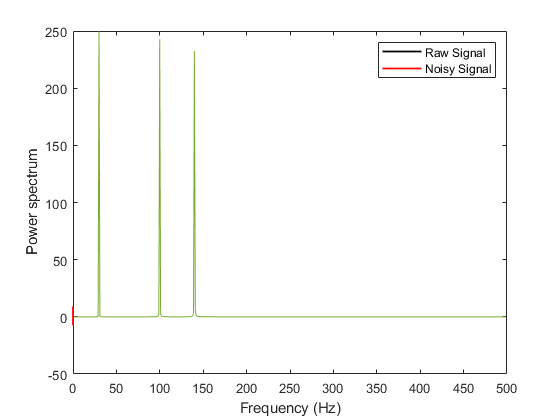

legend('Raw Signal', 'Noisy Signal');

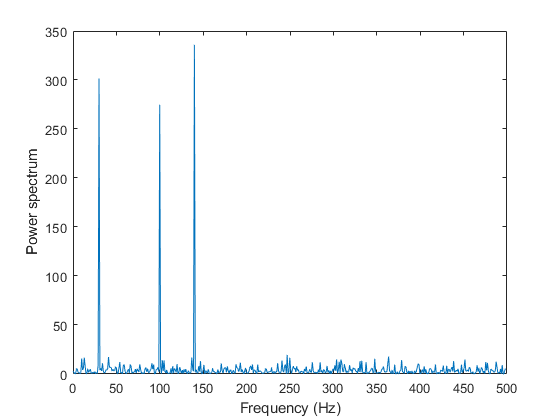

figure(3);
n=length(ts); % degree
fs = fft(ys, n); % fft
psd = fs.*conj(fs)/n; % power spectrum
ws = 1/(dt*n)*(0:n); % x-axis of freqs in Hz
L = 1:floor(n/2);
plot(ws(L), psd(L));
ylabel('Power spectrum');
xlabel('Frequency (Hz)');

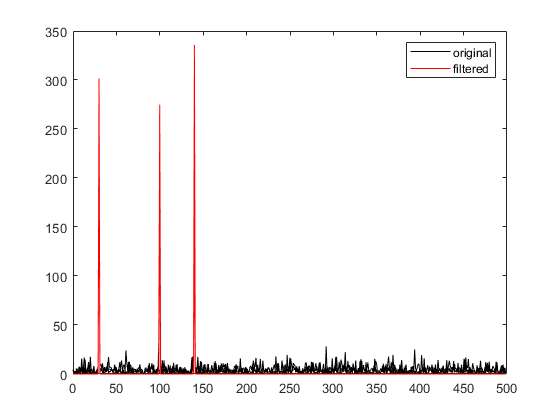


%filter the noise using psd
indicies = psd>50;
psd2 = psd.*indicies;
figure(4);
plot(ws(L), psd(L), 'k');
hold on;
plot(ws(L), psd2(L), 'r');
legend('original', 'filtered');


zs = fs.*indicies;
filtered_ys = ifft(zs);

figure(5);
plot(ts(1:size(ts,2)/5), xs(1:size(ts,2)/5), 'b', 'LineWidth', 1.3);

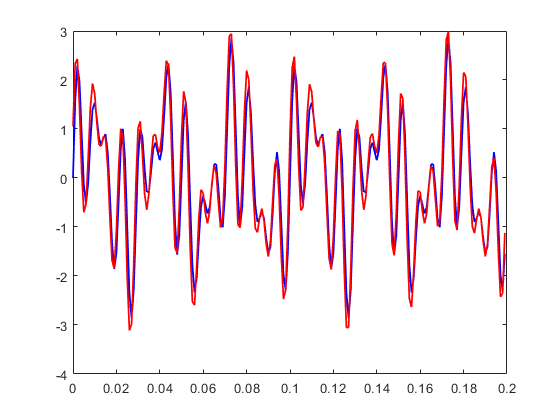

hold on;
plot(ts(1:size(ts,2)/5), filtered_ys(1:size(ts,2)/5), 'r', 'LineWidth', 1.3);